## * CALISTA MAIN SCRIPT *

Example 6. iPSC differentiation into mesodermal and endodermal cells (`Example_6_BARGAJE_scRT_qPCR_GUI.m` script in the main folder of CALISTA)

Analysis of RT-qPCR data of Bargaje et al. ([Bargaje, et al, Cell population structure prior to bifurcation predicts efficiency of directed differentiation in human induced pluripotent cells. Proc. Natl. Acad. Sci. U. S. A. 114, 2271– 2276 (2017)](https://www.pnas.org/content/114/9/2271.long)).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
curr_path='C:\Users\npgao\polybox\AAA ETH project CALISTA\CALISTA-MATLAB 1.2 dropout\CALISTA-MATLAB 1.2.1';
% In MacOS
% curr_path='/Users/nan/polybox/AAA ETH project CALISTA/CALISTA-MATLAB 1.2 dropout/CALISTA-MATLAB 1.2.1';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Bargaje dataset (available in the subfolder *EXAMPLES/BARGAJE*).

%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=1; % Single-cell RT-qPCR CT data
INPUTS.format_data=1; % Rows= cells and Columns= genes with time/stage info in the last column
%
% Specify single-cell clustering settings
INPUTS.optimize=1; % Find the optimal number of clusters
%
% Specify path analysis settings
INPUTS.plot_fig=1; % Plot figure of smoothened gene expression along path
INPUTS.hclustering=1; % Perform hierarchical clustering of gene expression for each path 
INPUTS.method=2; % Use pairwise correlation for the gene co-expression network (value_cutoff=0.8, pvalue_cutoff=0.01)
INPUTS.path_auto=0; % Manually define paths for further analysis


##  Analysis with CALISTA:

% -UPLOAD AND PRE_PROCESS DATA

% -SINGLE-CELL CLUSTERING

% -RECONSTRUCTION OF LINEAGE PROGRESSION

% -DETERMINATION OF TRANSITION GENES

% -PSEUDOTEMPORAL ORDERING OF CELLS

% -LANDSCAPE PLOTTING

% -PATH ANALYSIS



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  0.00

Selecting most variable genes...

Normalizing the data...

Finishing setup of the CALISTA data structure...

DONE.

Detecting the optimal number of clusters with Eigengap heuristics...

CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Constructing consensus matrix...
Elapsed time is 0.352735 seconds.


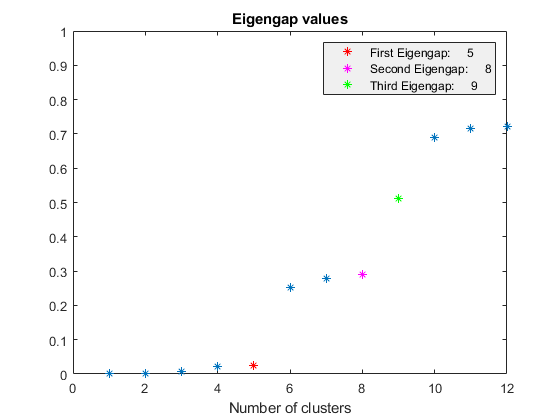


CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Performing clustering based on consensus matrix...

Constructing consensus matrix...

Kmedois...
Elapsed time is 7.908401 seconds.

Plotting...


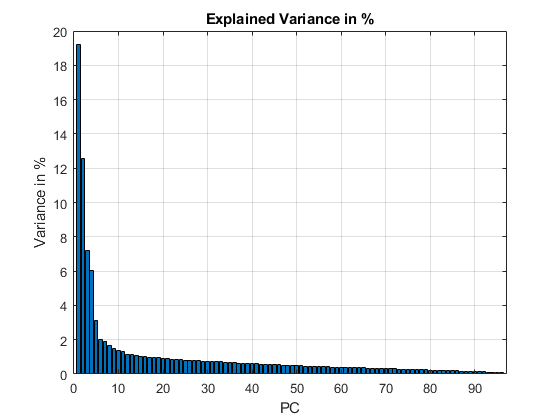

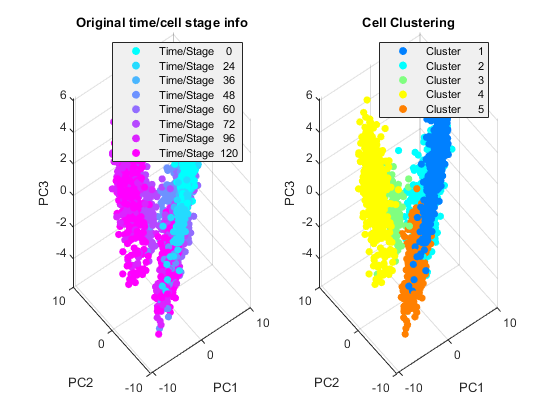

Elapsed time is 12.270246 seconds.

DONE.

CALISTA_transition is running...


** GUI displaying top   10 cluster distances **


CALISTA_LI_GUI;

During the lineage inference step, CALISTA automatically generates and displays a lineage graph, obtained by adding an edge between two clusters in increasing cluster distances, until all clusters are connected to at least one other cluster. Subsequently, users can manually add or remove one edge at time based on the cluster distances.

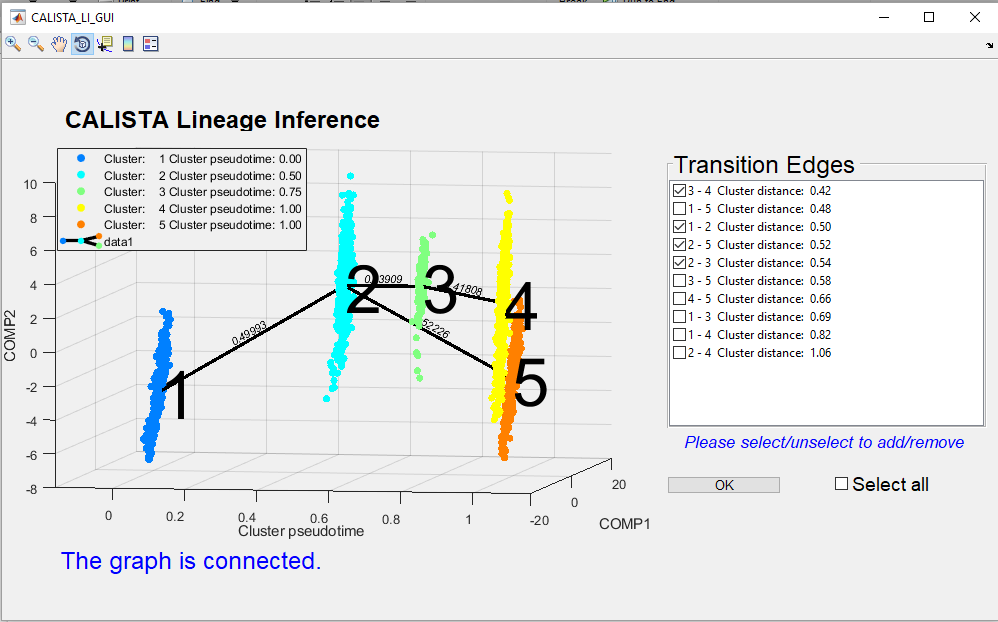

**ATTENTION:** 

- select (or unselect) checkboxes to add (or remove) specific edges. To select (or unselect) all edges use the “Select all” checkbox.

- to finalize the lineage progression (by pressing the “OK” button), the final graph must be connected (i.e. there exists a path from any node/cluster to any other node/cluster in the graph).